## BECS4 Optimization Methods Final Project

#### Introduction

The detection and classification of handwritten digits is a very common task for the introduction to neural networks. For this project we use a prewritten neural network workflow from [Rodrigo Sánchez Molina](https://github.com/rsanchezm98) which is based on the coursery course on deep learning. 

The mnist data on handwritten digits is already preprocessed and ready to use.

Github:[https://github.com/rsanchezm98/neural-network-from-scratch.git](https://github.com/rsanchezm98/neural-network-from-scratch.git)

Originaly there are **60'000** digits to train the model. To increase the difficulty and have a better comparability between methods, only **20'000** digits were used. 

**Explanation for the usage of genetic algorithms in neural networks**

https://towardsdatascience.com/gas-and-nns-6a41f1e8146d

### NN-Architecture

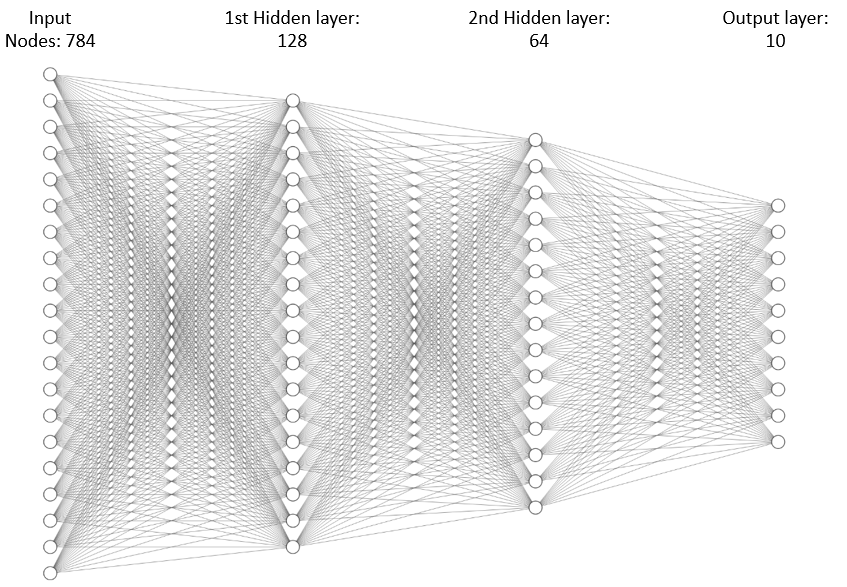

#### Input digits (28X28)

#### Project goal:

The first goal of the project is to evaluate different optimization methods to imporve the backpropagation of the model. The methods used are:

- Gradient descent 

- Mini-batch gradient descent 

- Stochastic gradient descent -X

- Adagrad. -X

- Adadelta. -> Eric

- RMSprop.

- Adam. -X

The second goal is to implement a genetic algorithm which finds the best initial weights for the first hidden layer to increase the accuracy. 

As a workflow template we use the publication of Ecer et al. https://www.mdpi.com/1099-4300/22/11/1239

The following steps were implemented:

- Train 10 individual models over 3 epochs with random weights. 

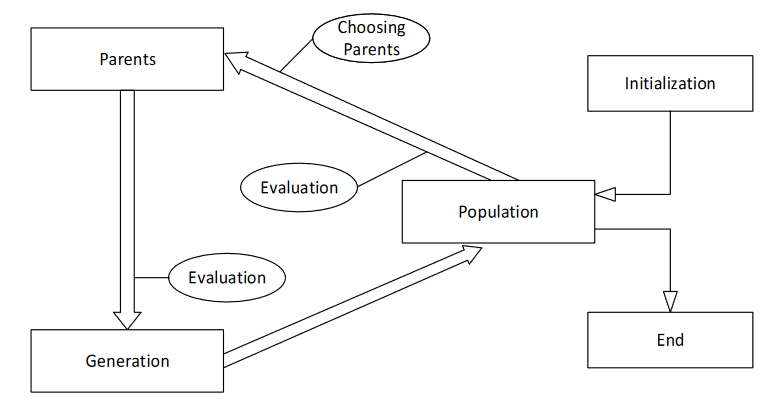

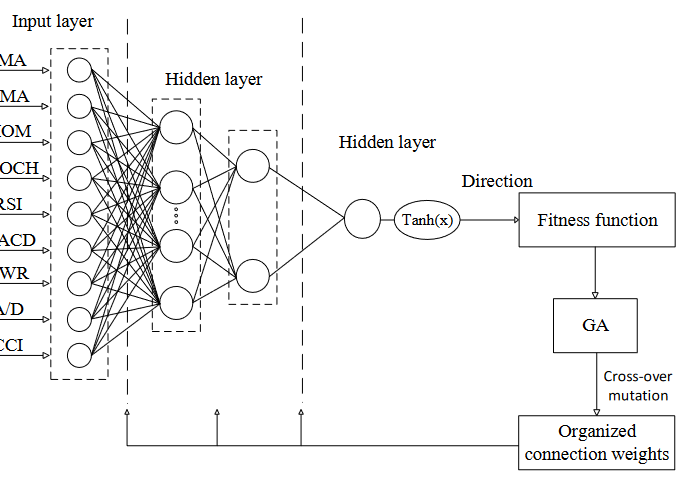

#### Data preprocessing

cd 'C:\Users\kevin yar\OneDrive - ZHAW\KEVIN STUFF\ZHAW\_PYTHON_R\_GITHUB\becs4\neural_network_mninst'


%% training data
disp('Loading data...')

% load train data
train_data = load('mnist_train.csv');

%reduce data volume to increase difficulty
train_data = train_data(1:10000,:);

labels = train_data(:,1);
y = zeros(10,length(train_data)); % output labels for training
for i = 1:length(train_data)
    %one hot encoding
    y(labels(i)+1,i) = 1;
end

% preprocessing
images = train_data(:,2:785);
images = images/255;
images = images'; % Input vectors for training

%% test data
    
% load test data
test_data = load('mnist_test.csv');
%reduce test data
test_data = test_data(1:5000, :);

test_labels = test_data(:,1);
test_y = zeros(10 ,length(test_data));
for i = 1:length(test_data)
    test_y(test_labels(i)+1,i) = 1;
end

% preproessing
test_images = test_data(:,2:785);
% normalize data
test_images = test_images/255;
% transposing
test_images = test_images';

%%

%set NN size
size_hl1 = 128; % Number of neurons in the first hidden layer
size_hl2 = 64; % Number of neurons in the second hidden layer

Loading data...


Starting epoch 1


Epochs:

     1



Evaluating model


Accuracy: 

93.150000

 %


Epochs:

     2



Evaluating model


Accuracy: 

95.380000

 %


Epochs:

     3



Evaluating model


Accuracy: 

96.260000

 %


Epochs:

     4



Evaluating model


Accuracy: 

96.790000

 %


Epochs:

     5



Evaluating model


Accuracy: 

97.090000

 %


Epochs:

     6



Evaluating model


Accuracy: 

97.540000

 %


Epochs:

     7



Evaluating model


Accuracy: 

97.580000

 %


Epochs:

     8



Evaluating model


Accuracy: 

97.600000

 %


Epochs:

     9



Evaluating model


Accuracy: 

97.670000

 %


Epochs:

    10



Evaluating model


Accuracy: 

98.020000

 %


Done



%set learning rate
lr = 0.001;

**Train 10 models**